# 做2022年VaR的预测

方法对比：Historical simulation, mean-variance

We use forecast volatilites to estimate VaR.

%% load data
clear,clc
database=load("VolFcst_normal_SP500_size750_20220707.mat");
D=readtable("SP500_0608.xlsx");
forecast_index=D.Date>=datetime(2022,1,1);
SaveVaRNameSuffix='SP500_20220716';
SaveTxtName='VaR_SP500_2020220716.txt';

Preparation

vf_HAR=database.vf_HAR;
vf_GJR=database.vf_GJR;
vf_RSGARCH=database.vf_RSGARCH;
logRet=D.Return(forecast_index);
TimeLine=D.Date(forecast_index);
T=length(logRet); % forecast window
ConfidenceLevel=[0.25 0.5 1 2.5 5 7.5 10]*0.01;
FigureVaRIndex=[3,5,7];% use FigureVaRIndex of ConfidenceLevel to figure VaR

## 历史模拟法与Variance-covariance

hVaR = zeros(size(logRet,1),length(ConfidenceLevel)); % historical simulation
pVaR = zeros(size(logRet,1),length(ConfidenceLevel)); % variance-covariance normal distribution
pVaRT = zeros(size(logRet,1),length(ConfidenceLevel));% variance-covariance t distribution
for i = 1 : T
    %历史模拟法
    historic_return = D.Return(find(forecast_index,1)+i-251:find(forecast_index,1)+i-2);
    confidence = prctile(historic_return, ConfidenceLevel*100);
    hVaR(i, :) = confidence;
    % innovation normal distributed
    pVaR(i, :) = norminv(ConfidenceLevel,mean(historic_return),std(historic_return));    
    % innovation student-t distributed
    fit_data=fitdist(historic_return,"tLocationScale");
    pVaRT(i, :) = tinv(ConfidenceLevel,fit_data.nu)*fit_data.sigma+fit_data.mu;
end
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'历史模拟法. \n');fclose(ftxt);
TableOutput=tableVaRPredict(hVaR,logRet,ConfidenceLevel)%历史模拟法

TableOutput = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075    CL0.1
                        ________    _______    _______    _______    _______    _______    _____

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075      0.1
    Failures                  5           6          8         10         16         21       28
    Kupiec Test           21.09       19.59      20.38      13.98      17.56      19.62    27.38
    Significance              1     0.99999    0.99999    0.99982    0.99997    0.99999        1


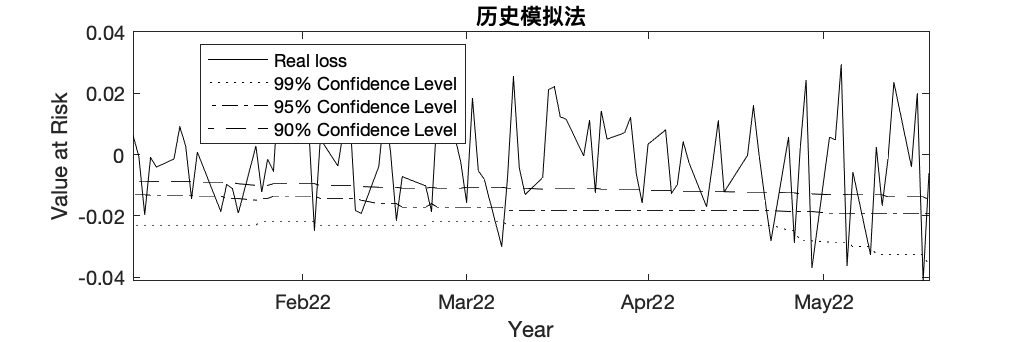

writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',false,'WriteRowNames',true)  
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'\n');fclose(ftxt);
figureVaR(hVaR(:,FigureVaRIndex),logRet,TimeLine);
title('历史模拟法')

table2latex(TableOutput(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & \textbf{21.09}$^{***}$ & \textbf{19.59}$^{***}$ & \textbf{20.38}$^{***}$ & \textbf{13.98}$^{***}$ & \textbf{17.56}$^{***}$ & \textbf{19.62}$^{***}$ & \textbf{27.38}$^{***}$ \\ 
\hline 
\end{tabular}


ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'Variance-covariance innovation正态分布. \n');fclose(ftxt);
TableOutput=tableVaRPredict(pVaR,logRet,ConfidenceLevel)% normal distribution

TableOutput = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05    CL0.075    CL0.1
                        ________    _______    ______    _______    ______    _______    _____

    Confidence level     0.0025      0.005      0.01      0.025      0.05      0.075       0.1
    Failures                  8          8        12         15        19         23        27
    Kupiec Test           41.23      30.58     39.87      31.56     26.22      24.82     24.81
    Significance              1          1         1          1         1          1         1


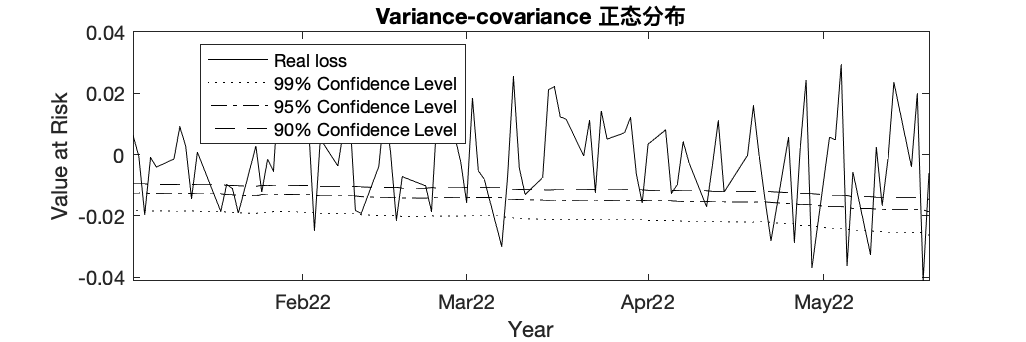

writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',false,'WriteRowNames',true)  
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'\n');fclose(ftxt);
figureVaR(pVaR(:,FigureVaRIndex),logRet,TimeLine);
title('Variance-covariance 正态分布')

table2latex(TableOutput(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & \textbf{41.23}$^{***}$ & \textbf{30.58}$^{***}$ & \textbf{39.87}$^{***}$ & \textbf{31.56}$^{***}$ & \textbf{26.22}$^{***}$ & \textbf{24.82}$^{***}$ & \textbf{24.81}$^{***}$ \\ 
\hline 
\end{tabular}


ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'Variance-covariance innovation t分布. \n');fclose(ftxt);
TableOutput=tableVaRPredict(pVaRT,logRet,ConfidenceLevel)% student-t distribution

TableOutput = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05    CL0.075    CL0.1
                        ________    _______    ______    _______    ______    _______    _____

    Confidence level     0.0025      0.005      0.01      0.025      0.05      0.075       0.1
    Failures                  3          7         9         15        19         26        28
    Kupiec Test            9.71      24.93     24.91      31.56     26.22      33.46     27.38
    Significance        0.99817          1         1          1         1          1         1


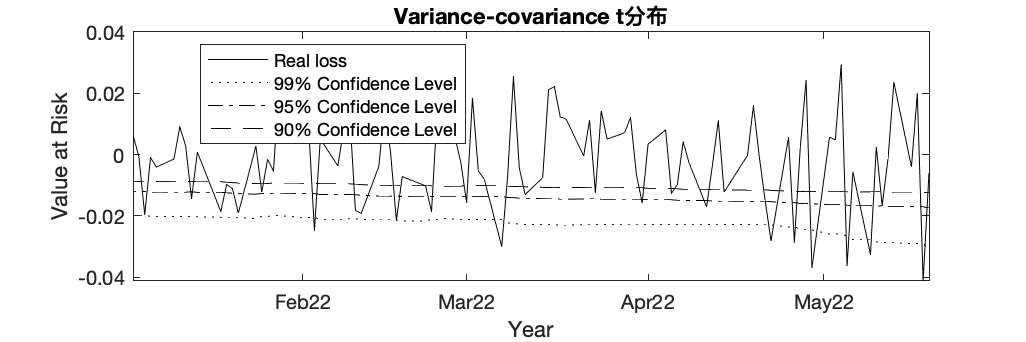

writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',false,'WriteRowNames',true)  
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'\n');fclose(ftxt);
figureVaR(pVaRT(:,FigureVaRIndex),logRet,TimeLine);
title('Variance-covariance t分布')

table2latex(TableOutput(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & \textbf{9.71}$^{***}$ & \textbf{24.93}$^{***}$ & \textbf{24.91}$^{***}$ & \textbf{31.56}$^{***}$ & \textbf{26.22}$^{***}$ & \textbf{33.46}$^{***}$ & \textbf{27.38}$^{***}$ \\ 
\hline 
\end{tabular}


% save(['HSVaR' SaveVaRNameSuffix],'hVaR','logRet');
% save(['VaCovVaR' SaveVaRNameSuffix],'pVaR','pVaRT','logRet');

## GARCH VaR

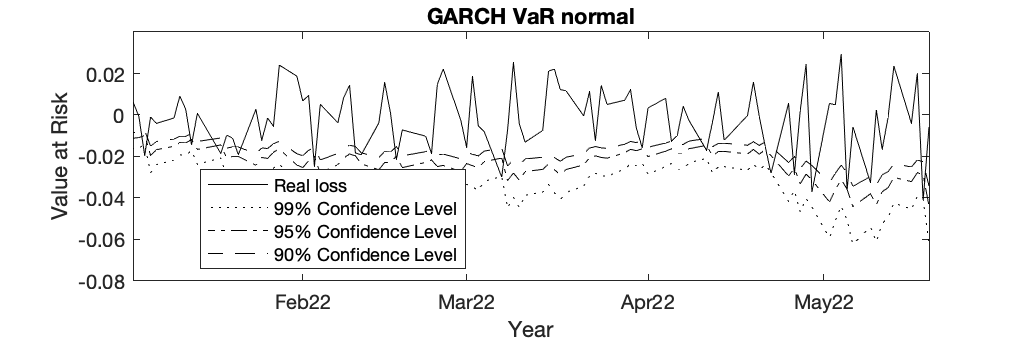

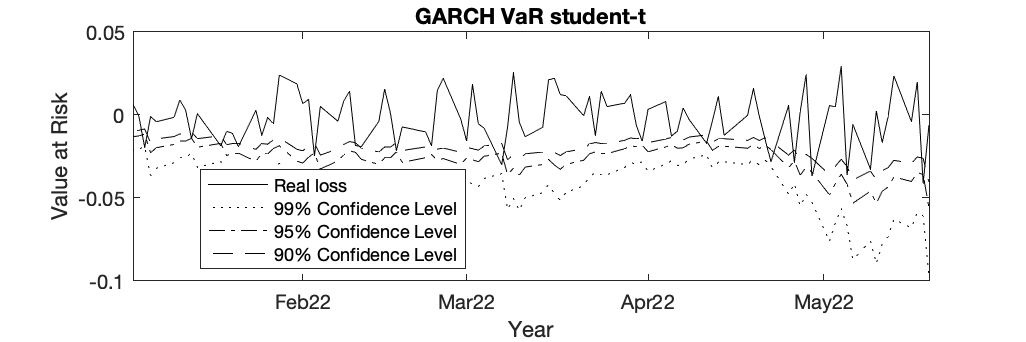

Model_Name='GARCH';
vf=database.vf_GARCH;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

% GARCH_VaR_normal=Output.VaR_normal;
% GARCH_VaR_t=Output.VaR_t;
Output.Table_normal

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075     CL0.1 
                        ________    _______    _______    _______    _______    _______    _______

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075        0.1
    Failures                  1           1          4          7         12         16         20
    Kupiec Test            1.34        0.43       5.44       6.02       8.17       8.85       9.86
    Significance        0.75297     0.48801    0.98032    0.98586    0.99574    0.99707    0.99831


table2latex(Output.Table_normal(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 1.34 & 0.43 & \textbf{5.44}$^{**}$ & \textbf{6.02}$^{**}$ & \textbf{8.17}$^{***}$ & \textbf{8.85}$^{***}$ & \textbf{9.86}$^{***}$ \\ 
\hline 
\end{tabular}

Output.Table_t

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05     CL0.075     CL0.1 
                        ________    _______    ______    _______    _______    _______    _______

    Confidence level     0.0025       0.005     0.01       0.025       0.05      0.075        0.1
    Failures                  0           0        1           3         10         13         17
    Kupiec Test            0.48        0.96        0        0.14       4.58       4.15       5.28
    Significance        0.51158     0.67281        0     0.29172    0.96765    0.95837    0.97843


table2latex(Output.Table_t(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 0.48 & 0.96 & 0 & 0.14 & \textbf{4.58}$^{**}$ & \textbf{4.15}$^{**}$ & \textbf{5.28}$^{**}$ \\ 
\hline 
\end{tabular}

% save([Model_Name,'_VaR' SaveVaRNameSuffix],[Model_Name,'_VaR_normal'],[Model_Name,'_VaR_t'],'logRet');

## CPGARCH VaR

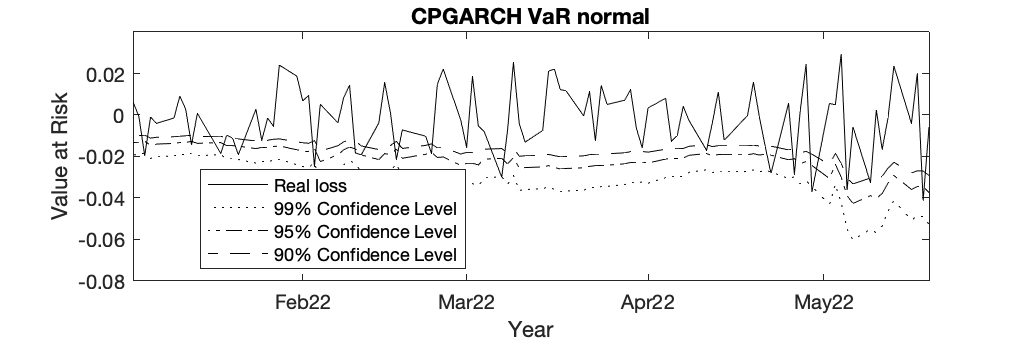

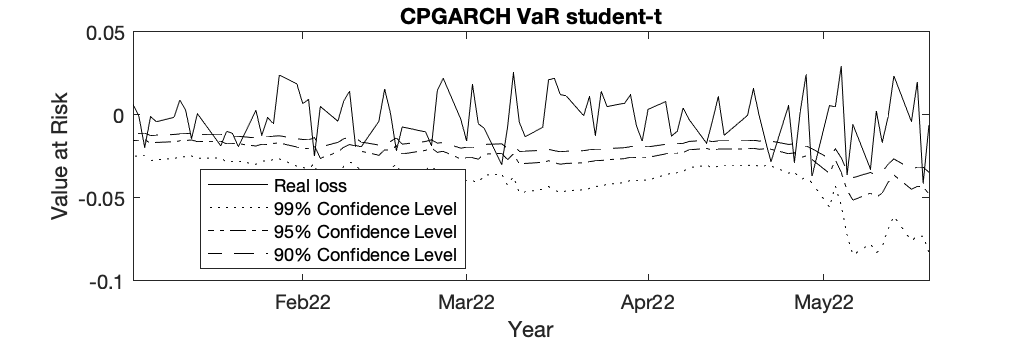

Model_Name='CPGARCH';
vf=database.vf_CPGARCH;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

% CPGARCH_VaR_normal=Output.VaR_normal;
% CPGARCH_VaR_t=Output.VaR_t;
Output.Table_normal

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075     CL0.1 
                        ________    _______    _______    _______    _______    _______    _______

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075        0.1
    Failures                  0           0          5          9         13         16         19
    Kupiec Test            0.48        0.96        8.6      11.07      10.27       8.85        8.2
    Significance        0.51158     0.67281    0.99664    0.99912    0.99865    0.99707    0.99581


table2latex(Output.Table_normal(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 0.48 & 0.96 & \textbf{8.6}$^{***}$ & \textbf{11.07}$^{***}$ & \textbf{10.27}$^{***}$ & \textbf{8.85}$^{***}$ & \textbf{8.2}$^{***}$ \\ 
\hline 
\end{tabular}

Output.Table_t

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075    CL0.1 
                        ________    _______    _______    _______    _______    _______    ______

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075       0.1
    Failures                  0           0          0          6          9         14        16
    Kupiec Test            0.48        0.96       1.93       3.94       3.11       5.55      4.03
    Significance        0.51158     0.67281    0.83524    0.95285    0.92219    0.98152    0.9553


table2latex(Output.Table_t(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 0.48 & 0.96 & 1.93 & \textbf{3.94}$^{**}$ & \textbf{3.11}$^{*}$ & \textbf{5.55}$^{**}$ & \textbf{4.03}$^{**}$ \\ 
\hline 
\end{tabular}

% save([Model_Name,'_VaR' SaveVaRNameSuffix],[Model_Name,'_VaR_normal'],[Model_Name,'_VaR_t'],'logRet');

## CPGARCHiteration VaR

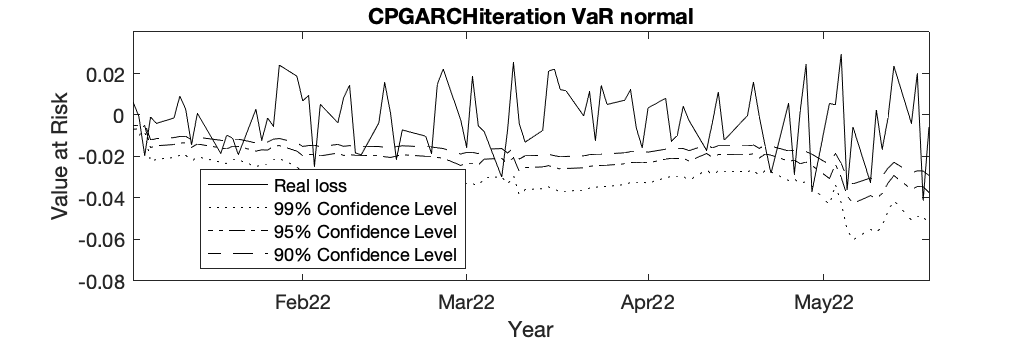

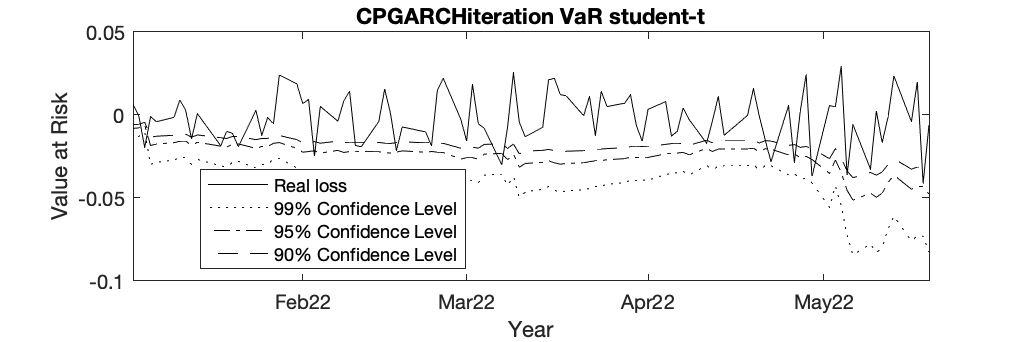

Model_Name='CPGARCHiteration';
vf=database.vf_CPGARCHiteration;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

% CPGARCHiteration_VaR_normal=Output.VaR_normal;
% CPGARCHiteration_VaR_t=Output.VaR_t;
Output.Table_normal

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075    CL0.1 
                        ________    _______    _______    _______    _______    _______    ______

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075       0.1
    Failures                  1           1          4          7         10         16        18
    Kupiec Test            1.34        0.43       5.44       6.02       4.58       8.85      6.67
    Significance        0.75297     0.48801    0.98032    0.98586    0.96765    0.99707    0.9902


table2latex(Output.Table_normal(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 1.34 & 0.43 & \textbf{5.44}$^{**}$ & \textbf{6.02}$^{**}$ & \textbf{4.58}$^{**}$ & \textbf{8.85}$^{***}$ & \textbf{6.67}$^{***}$ \\ 
\hline 
\end{tabular}

Output.Table_t

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05     CL0.075    CL0.1 
                        ________    _______    ______    _______    _______    _______    ______

    Confidence level     0.0025       0.005     0.01       0.025       0.05     0.075        0.1
    Failures                  1           1        1           4          7        11         16
    Kupiec Test            1.34        0.43        0        0.91       0.94      1.89       4.03
    Significance        0.75297     0.48801        0     0.65989    0.66772    0.8308     0.9553


table2latex(Output.Table_t(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 1.34 & 0.43 & 0 & 0.91 & 0.94 & 1.89 & \textbf{4.03}$^{**}$ \\ 
\hline 
\end{tabular}

% save([Model_Name,'_VaR' SaveVaRNameSuffix],[Model_Name,'_VaR_normal'],[Model_Name,'_VaR_t'],'logRet');

## GJR VaR

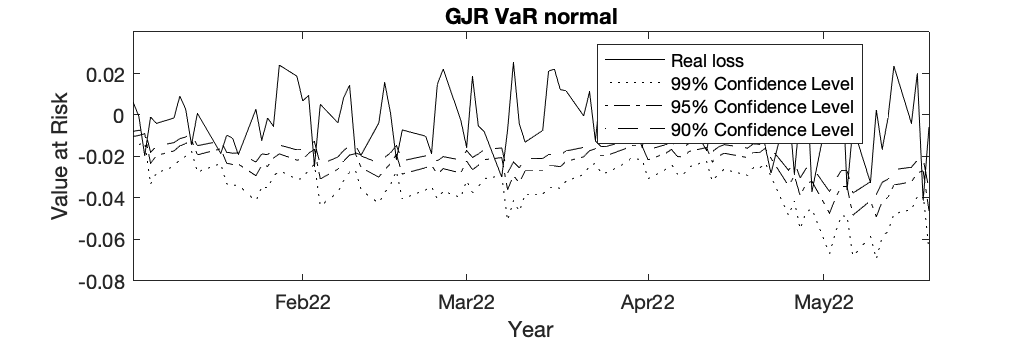

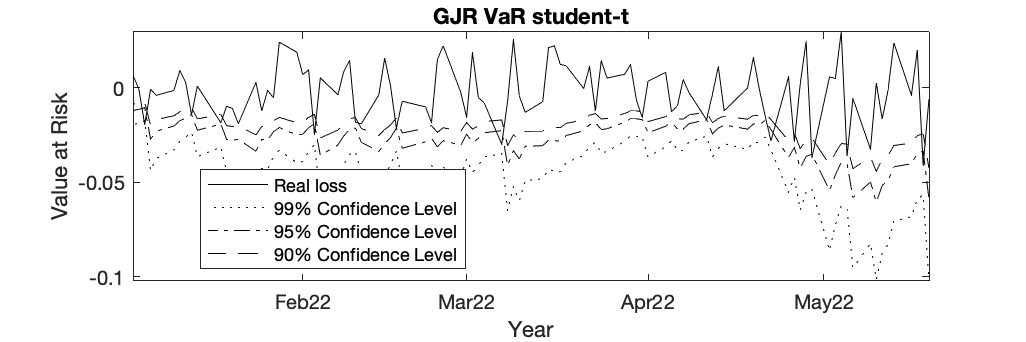

Model_Name='GJR';
vf=database.vf_GJR;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

% GJR_VaR_normal=Output.VaR_normal;
% GJR_VaR_t=Output.VaR_t;
Output.Table_normal

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075     CL0.1 
                        ________    _______    _______    _______    _______    _______    _______

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075        0.1
    Failures                  1           1          4          5         12         15         17
    Kupiec Test            1.34        0.43       5.44       2.21       8.17       7.13       5.28
    Significance        0.75297     0.48801    0.98032    0.86288    0.99574    0.99242    0.97843


table2latex(Output.Table_normal(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 1.34 & 0.43 & \textbf{5.44}$^{**}$ & 2.21 & \textbf{8.17}$^{***}$ & \textbf{7.13}$^{***}$ & \textbf{5.28}$^{**}$ \\ 
\hline 
\end{tabular}

Output.Table_t

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05     CL0.075     CL0.1 
                        ________    _______    ______    _______    _______    _______    _______

    Confidence level     0.0025       0.005     0.01       0.025       0.05      0.075        0.1
    Failures                  0           0        1           4          9         14         15
    Kupiec Test            0.48        0.96        0        0.91       3.11       5.55       2.93
    Significance        0.51158     0.67281        0     0.65989    0.92219    0.98152    0.91305


table2latex(Output.Table_t(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 0.48 & 0.96 & 0 & 0.91 & \textbf{3.11}$^{*}$ & \textbf{5.55}$^{**}$ & \textbf{2.93}$^{*}$ \\ 
\hline 
\end{tabular}

% save([Model_Name,'_VaR' SaveVaRNameSuffix],[Model_Name,'_VaR_normal'],[Model_Name,'_VaR_t'],'logRet');

## CPGJR VaR

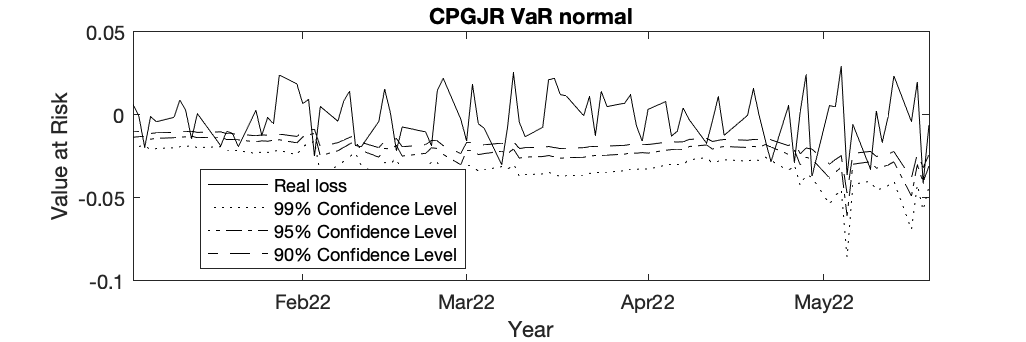

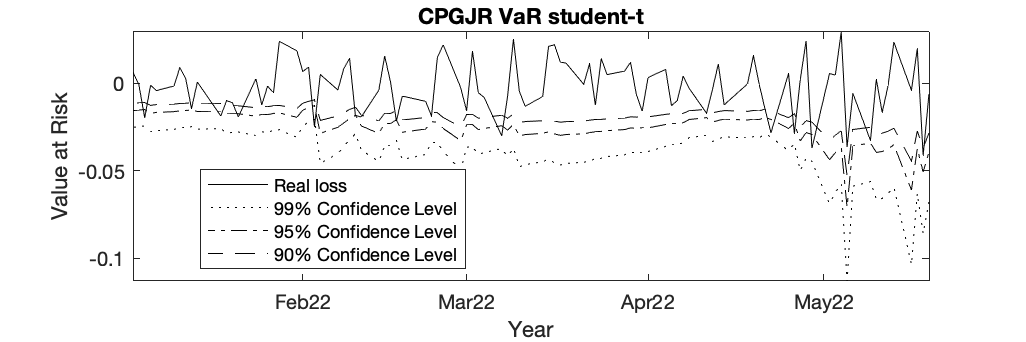

Model_Name='CPGJR';
vf=database.vf_CPGJR;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

% CPGJR_VaR_normal=Output.VaR_normal;
% CPGJR_VaR_t=Output.VaR_t;
Output.Table_normal

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075    CL0.1 
                        ________    _______    _______    _______    _______    _______    ______

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075       0.1
    Failures                  1           1          3          8         13         16        18
    Kupiec Test            1.34        0.43        2.8       8.41      10.27       8.85      6.67
    Significance        0.75297     0.48801    0.90574    0.99627    0.99865    0.99707    0.9902


table2latex(Output.Table_normal(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 1.34 & 0.43 & \textbf{2.8}$^{*}$ & \textbf{8.41}$^{***}$ & \textbf{10.27}$^{***}$ & \textbf{8.85}$^{***}$ & \textbf{6.67}$^{***}$ \\ 
\hline 
\end{tabular}

Output.Table_t

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05     CL0.075     CL0.1 
                        ________    _______    ______    _______    _______    _______    _______

    Confidence level     0.0025       0.005     0.01       0.025       0.05      0.075        0.1
    Failures                  0           1        1           6         10         13         17
    Kupiec Test            0.48        0.43        0        3.94       4.58       4.15       5.28
    Significance        0.51158     0.48801        0     0.95285    0.96765    0.95837    0.97843


table2latex(Output.Table_t(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 0.48 & 0.43 & 0 & \textbf{3.94}$^{**}$ & \textbf{4.58}$^{**}$ & \textbf{4.15}$^{**}$ & \textbf{5.28}$^{**}$ \\ 
\hline 
\end{tabular}

% save([Model_Name,'_VaR' SaveVaRNameSuffix],[Model_Name,'_VaR_normal'],[Model_Name,'_VaR_t'],'logRet');

## CPGJRiteration VaR

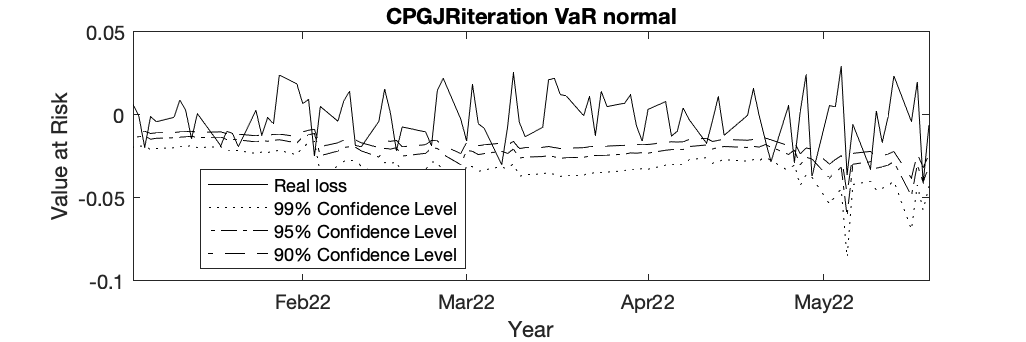

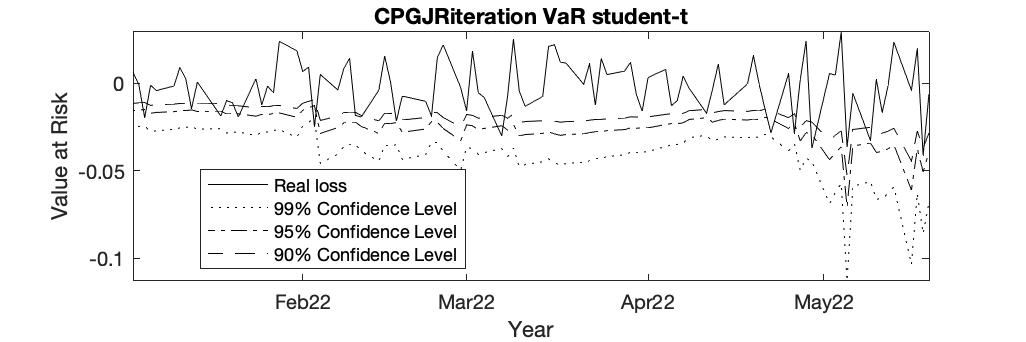

Model_Name='CPGJRiteration';
vf=database.vf_CPGJRiteration;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

% CPGJRiteration_VaR_normal=Output.VaR_normal;
% CPGJRiteration_VaR_t=Output.VaR_t;
Output.Table_normal

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075    CL0.1 
                        ________    _______    _______    _______    _______    _______    ______

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075       0.1
    Failures                  1           1          3          8         12         16        18
    Kupiec Test            1.34        0.43        2.8       8.41       8.17       8.85      6.67
    Significance        0.75297     0.48801    0.90574    0.99627    0.99574    0.99707    0.9902


table2latex(Output.Table_normal(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 1.34 & 0.43 & \textbf{2.8}$^{*}$ & \textbf{8.41}$^{***}$ & \textbf{8.17}$^{***}$ & \textbf{8.85}$^{***}$ & \textbf{6.67}$^{***}$ \\ 
\hline 
\end{tabular}

Output.Table_t

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05    CL0.075     CL0.1 
                        ________    _______    ______    _______    ______    _______    _______

    Confidence level     0.0025       0.005     0.01       0.025      0.05      0.075        0.1
    Failures                  0           1        1           6         8         12         17
    Kupiec Test            0.48        0.43        0        3.94      1.89       2.92       5.28
    Significance        0.51158     0.48801        0     0.95285    0.8308    0.91251    0.97843


table2latex(Output.Table_t(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 0.48 & 0.43 & 0 & \textbf{3.94}$^{**}$ & 1.89 & \textbf{2.92}$^{*}$ & \textbf{5.28}$^{**}$ \\ 
\hline 
\end{tabular}

% save([Model_Name,'_VaR' SaveVaRNameSuffix],[Model_Name,'_VaR_normal'],[Model_Name,'_VaR_t'],'logRet');

## RSGARCH VaR

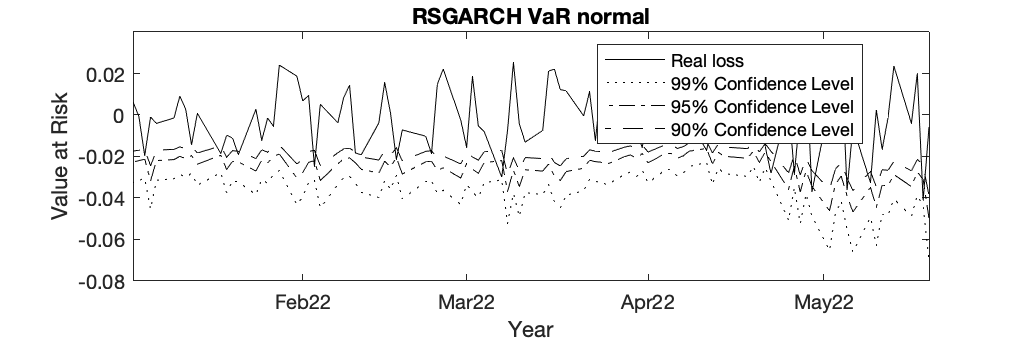

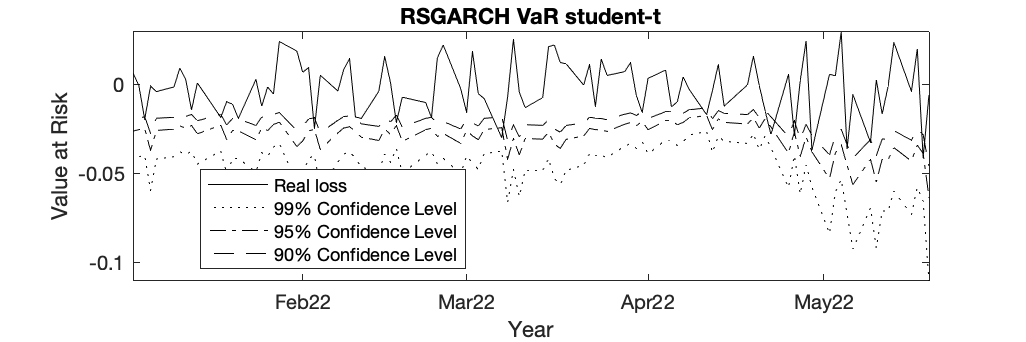

Model_Name='RSGARCH';
vf=database.vf_RSGARCH;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

% GJR_VaR_normal=Output.VaR_normal;
% GJR_VaR_t=Output.VaR_t;
Output.Table_normal

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05    CL0.075     CL0.1 
                        ________    _______    _______    _______    ______    _______    _______

    Confidence level     0.0025       0.005       0.01      0.025      0.05      0.075        0.1
    Failures                  0           0          0          3         8         12         17
    Kupiec Test            0.48        0.96       1.93       0.14      1.89       2.92       5.28
    Significance        0.51158     0.67281    0.83524    0.29172    0.8308    0.91251    0.97843


table2latex(Output.Table_normal(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 0.48 & 0.96 & 1.93 & 0.14 & 1.89 & \textbf{2.92}$^{*}$ & \textbf{5.28}$^{**}$ \\ 
\hline 
\end{tabular}

Output.Table_t

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075     CL0.1 
                        ________    _______    _______    _______    _______    _______    _______

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075        0.1
    Failures                  0           0          0          0          4          8         15
    Kupiec Test            0.48        0.96       1.93       4.86       0.15       0.09       2.93
    Significance        0.51158     0.67281    0.83524    0.97251    0.30146    0.23582    0.91305


table2latex(Output.Table_t(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 0.48 & 0.96 & 1.93 & \textbf{4.86}$^{**}$ & 0.15 & 0.09 & \textbf{2.93}$^{*}$ \\ 
\hline 
\end{tabular}

% save([Model_Name,'_VaR' SaveVaRNameSuffix],[Model_Name,'_VaR_normal'],[Model_Name,'_VaR_t'],'logRet');

## CPRSGARCH VaR

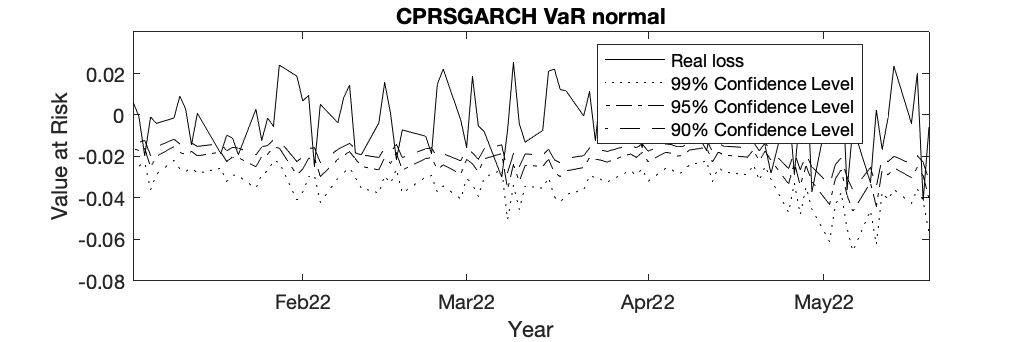

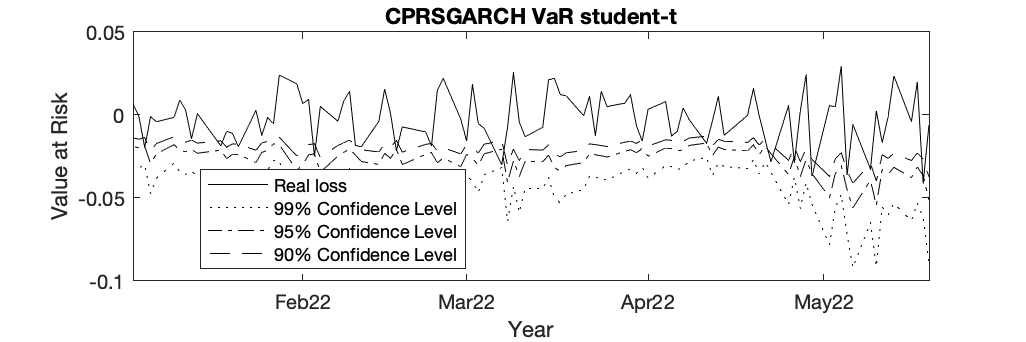

Model_Name='CPRSGARCH';
vf=database.vf_CPRSGARCH;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

% CPRSGARCH_VaR_normal=Output.VaR_normal;
% CPRSGARCH_VaR_t=Output.VaR_t;
Output.Table_normal

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05     CL0.075    CL0.1 
                        ________    _______    ______    _______    _______    _______    ______

    Confidence level     0.0025       0.005     0.01       0.025       0.05      0.075       0.1
    Failures                  0           1        1           6         11         15        18
    Kupiec Test            0.48        0.43        0        3.94       6.28       7.13      6.67
    Significance        0.51158     0.48801        0     0.95285    0.98779    0.99242    0.9902


table2latex(Output.Table_normal(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 0.48 & 0.43 & 0 & \textbf{3.94}$^{**}$ & \textbf{6.28}$^{**}$ & \textbf{7.13}$^{***}$ & \textbf{6.67}$^{***}$ \\ 
\hline 
\end{tabular}

Output.Table_t

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075     CL0.1 
                        ________    _______    _______    _______    _______    _______    _______

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075        0.1
    Failures                  0           0          0          1          9         10         17
    Kupiec Test            0.48        0.96       1.93       1.07       3.11       1.06       5.28
    Significance        0.51158     0.67281    0.83524    0.69905    0.92219    0.69678    0.97843


table2latex(Output.Table_t(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 0.48 & 0.96 & 1.93 & 1.07 & \textbf{3.11}$^{*}$ & 1.06 & \textbf{5.28}$^{**}$ \\ 
\hline 
\end{tabular}

% save([Model_Name,'_VaR' SaveVaRNameSuffix],[Model_Name,'_VaR_normal'],[Model_Name,'_VaR_t'],'logRet');

## CPRSGARCHiteration VaR

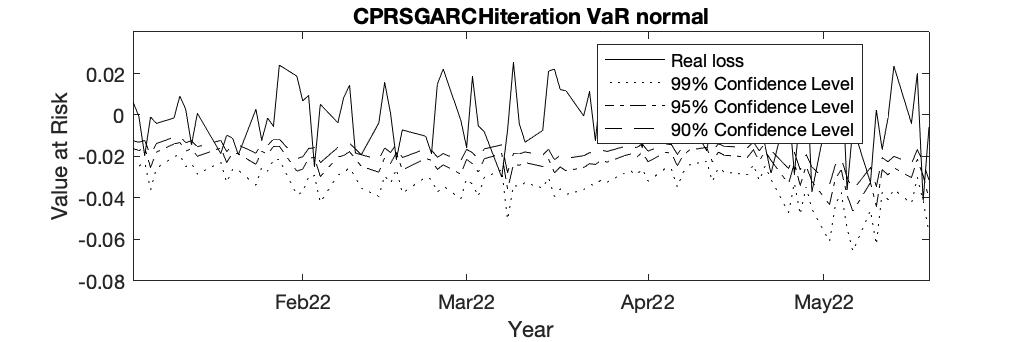

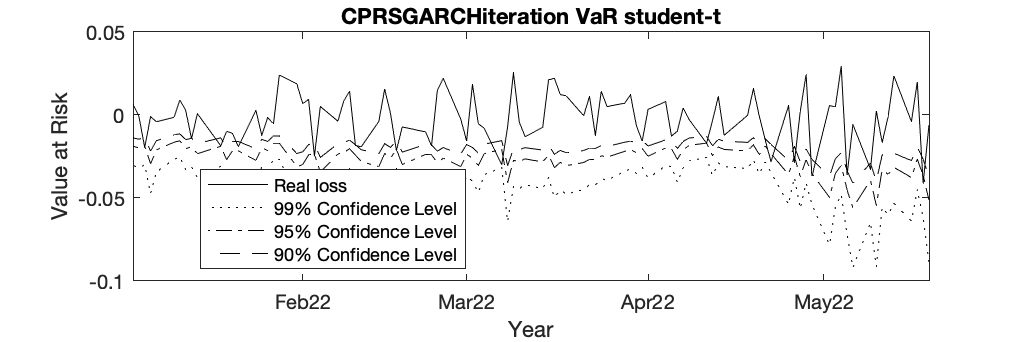

Model_Name='CPRSGARCHiteration';
vf=database.vf_CPRSGARCHiteration;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

% CPRSGARCHiteration_VaR_normal=Output.VaR_normal;
% CPRSGARCHiteration_VaR_t=Output.VaR_t;
Output.Table_normal

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05     CL0.075    CL0.1 
                        ________    _______    ______    _______    _______    _______    ______

    Confidence level     0.0025       0.005     0.01       0.025       0.05      0.075       0.1
    Failures                  0           1        1           6         12         15        18
    Kupiec Test            0.48        0.43        0        3.94       8.17       7.13      6.67
    Significance        0.51158     0.48801        0     0.95285    0.99574    0.99242    0.9902


table2latex(Output.Table_normal(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 0.48 & 0.43 & 0 & \textbf{3.94}$^{**}$ & \textbf{8.17}$^{***}$ & \textbf{7.13}$^{***}$ & \textbf{6.67}$^{***}$ \\ 
\hline 
\end{tabular}

Output.Table_t

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075    CL0.1 
                        ________    _______    _______    _______    _______    _______    ______

    Confidence level     0.0025       0.005       0.01      0.025       0.05     0.075        0.1
    Failures                  0           0          0          1          9        11         18
    Kupiec Test            0.48        0.96       1.93       1.07       3.11      1.89       6.67
    Significance        0.51158     0.67281    0.83524    0.69905    0.92219    0.8308     0.9902


table2latex(Output.Table_t(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 0.48 & 0.96 & 1.93 & 1.07 & \textbf{3.11}$^{*}$ & 1.89 & \textbf{6.67}$^{***}$ \\ 
\hline 
\end{tabular}

% save([Model_Name,'_VaR' SaveVaRNameSuffix],[Model_Name,'_VaR_normal'],[Model_Name,'_VaR_t'],'logRet');

## HAR VaR

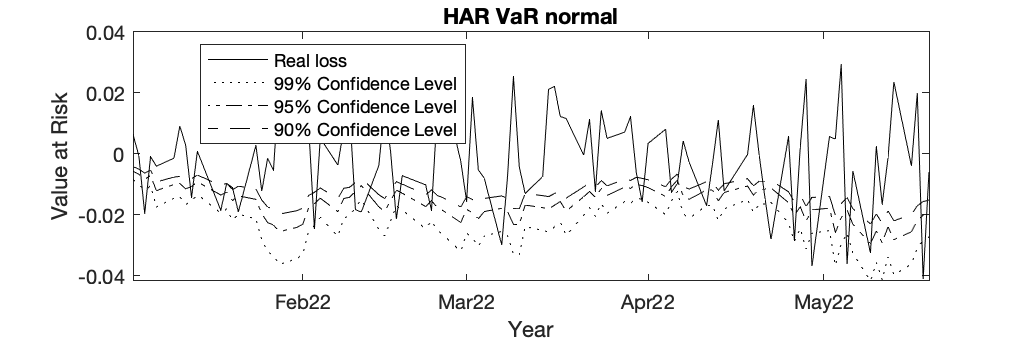

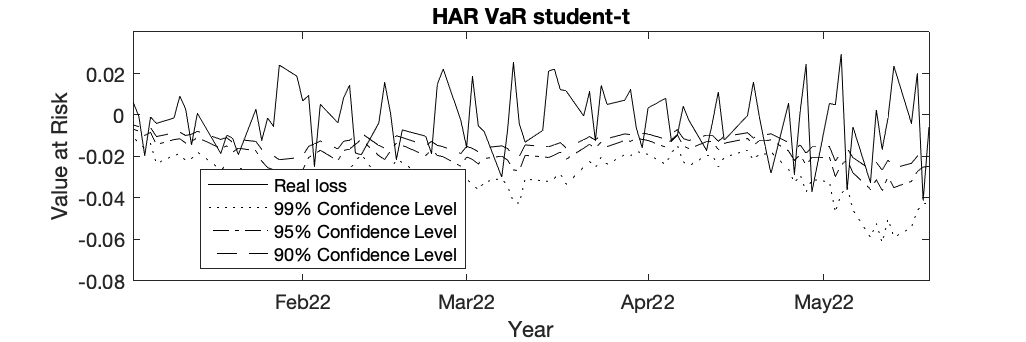

Model_Name='HAR';
vf=database.vf_HAR;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

% HAR_VaR_normal=Output.VaR_normal;
% HAR_VaR_t=Output.VaR_t;
Output.Table_normal

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05    CL0.075     CL0.1 
                        ________    _______    ______    _______    ______    _______    _______

    Confidence level     0.0025      0.005      0.01      0.025      0.05      0.075         0.1
    Failures                  7          8        12         18        21         22          25
    Kupiec Test           34.19      30.58     39.87      44.09     32.65      22.16       19.98
    Significance              1          1         1          1         1          1     0.99999


table2latex(Output.Table_normal(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & \textbf{34.19}$^{***}$ & \textbf{30.58}$^{***}$ & \textbf{39.87}$^{***}$ & \textbf{44.09}$^{***}$ & \textbf{32.65}$^{***}$ & \textbf{22.16}$^{***}$ & \textbf{19.98}$^{***}$ \\ 
\hline 
\end{tabular}

Output.Table_t

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05    CL0.075     CL0.1 
                        ________    _______    _______    _______    ______    _______    _______

    Confidence level     0.0025       0.005       0.01     0.025      0.05      0.075         0.1
    Failures                  1           3          6        13        20         22          24
    Kupiec Test            1.34        6.02      12.18     23.97     29.37      22.16       17.73
    Significance        0.75297     0.98586    0.99952         1         1          1     0.99997


table2latex(Output.Table_t(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & 1.34 & \textbf{6.02}$^{**}$ & \textbf{12.18}$^{***}$ & \textbf{23.97}$^{***}$ & \textbf{29.37}$^{***}$ & \textbf{22.16}$^{***}$ & \textbf{17.73}$^{***}$ \\ 
\hline 
\end{tabular}

% save([Model_Name,'_VaR' SaveVaRNameSuffix],[Model_Name,'_VaR_normal'],[Model_Name,'_VaR_t'],'logRet');

## CPHAR VaR

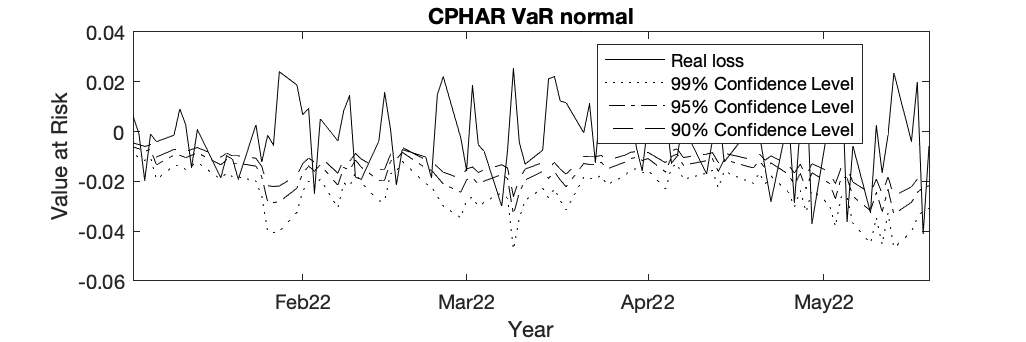

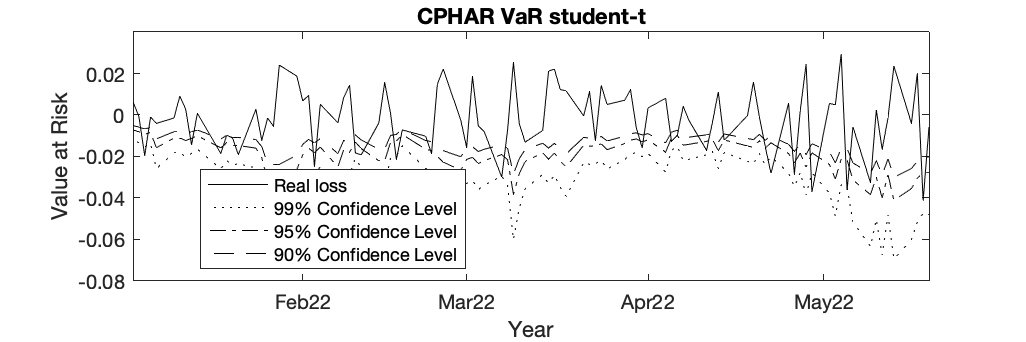

Model_Name='CPHAR';
vf=database.vf_CPHAR;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

% CPHAR_VaR_normal=Output.VaR_normal;
% CPHAR_VaR_t=Output.VaR_t;
Output.Table_normal

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05    CL0.075    CL0.1
                        ________    _______    ______    _______    ______    _______    _____

    Confidence level     0.0025      0.005      0.01      0.025      0.05      0.075       0.1
    Failures                  7          8        12         17        22         24        27
    Kupiec Test           34.19      30.58     39.87      39.77     36.06      27.59     24.81
    Significance              1          1         1          1         1          1         1


table2latex(Output.Table_normal(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & \textbf{34.19}$^{***}$ & \textbf{30.58}$^{***}$ & \textbf{39.87}$^{***}$ & \textbf{39.77}$^{***}$ & \textbf{36.06}$^{***}$ & \textbf{27.59}$^{***}$ & \textbf{24.81}$^{***}$ \\ 
\hline 
\end{tabular}

Output.Table_t

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05    CL0.075     CL0.1 
                        ________    _______    _______    _______    ______    _______    _______

    Confidence level     0.0025       0.005       0.01     0.025      0.05      0.075         0.1
    Failures                  2           3          6        13        19         22          25
    Kupiec Test            4.99        6.02      12.18     23.97     26.22      22.16       19.98
    Significance        0.97451     0.98586    0.99952         1         1          1     0.99999


table2latex(Output.Table_t(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & \textbf{4.99}$^{**}$ & \textbf{6.02}$^{**}$ & \textbf{12.18}$^{***}$ & \textbf{23.97}$^{***}$ & \textbf{26.22}$^{***}$ & \textbf{22.16}$^{***}$ & \textbf{19.98}$^{***}$ \\ 
\hline 
\end{tabular}

% save([Model_Name,'_VaR' SaveVaRNameSuffix],[Model_Name,'_VaR_normal'],[Model_Name,'_VaR_t'],'logRet');

## CPHARiteration VaR

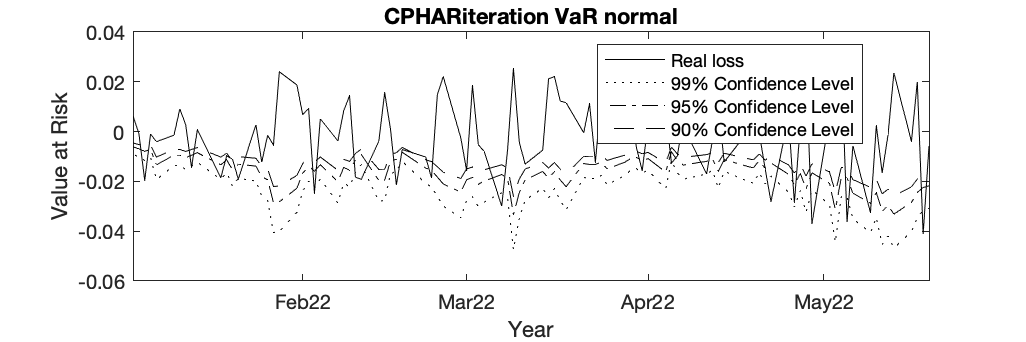

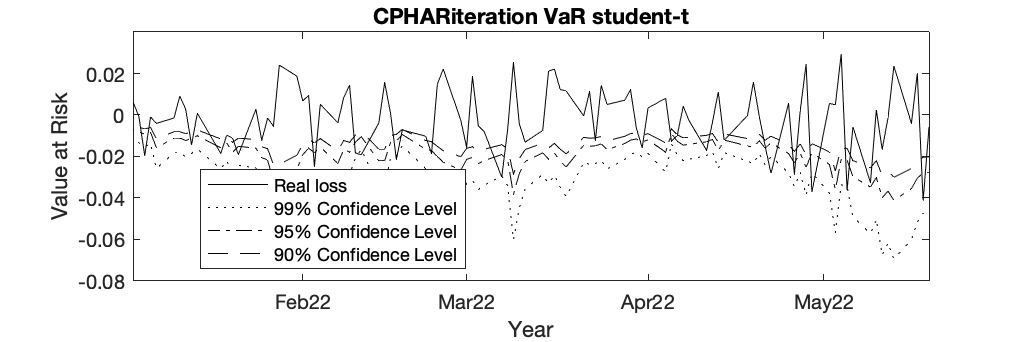

Model_Name='CPHARiteration';
vf=database.vf_CPHARiteration;
Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);

% CPHARiteration_VaR_normal=Output.VaR_normal;
% CPHARiteration_VaR_t=Output.VaR_t;
Output.Table_normal

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05    CL0.075    CL0.1
                        ________    _______    ______    _______    ______    _______    _____

    Confidence level     0.0025      0.005      0.01      0.025      0.05      0.075       0.1
    Failures                  8          9        13         17        21         22        26
    Kupiec Test           41.23      36.51     45.26      39.77     32.65      22.16     22.34
    Significance              1          1         1          1         1          1         1


table2latex(Output.Table_normal(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & \textbf{41.23}$^{***}$ & \textbf{36.51}$^{***}$ & \textbf{45.26}$^{***}$ & \textbf{39.77}$^{***}$ & \textbf{32.65}$^{***}$ & \textbf{22.16}$^{***}$ & \textbf{22.34}$^{***}$ \\ 
\hline 
\end{tabular}

Output.Table_t

ans = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05    CL0.075     CL0.1 
                        ________    _______    _______    _______    ______    _______    _______

    Confidence level     0.0025       0.005       0.01     0.025      0.05       0.075        0.1
    Failures                  2           3          7        15        19          21         24
    Kupiec Test            4.99        6.02      16.13     31.56     26.22       19.62      17.73
    Significance        0.97451     0.98586    0.99994         1         1     0.99999    0.99997


table2latex(Output.Table_t(3,:))

\begin{tabular}{llllllll}
& CL0.0025 & CL0.005 & CL0.01 & CL0.025 & CL0.05 & CL0.075 & CL0.1 \\ 
\hline 
Kupiec Test & \textbf{4.99}$^{**}$ & \textbf{6.02}$^{**}$ & \textbf{16.13}$^{***}$ & \textbf{31.56}$^{***}$ & \textbf{26.22}$^{***}$ & \textbf{19.62}$^{***}$ & \textbf{17.73}$^{***}$ \\ 
\hline 
\end{tabular}

% save([Model_Name,'_VaR' SaveVaRNameSuffix],[Model_Name,'_VaR_normal'],[Model_Name,'_VaR_t'],'logRet');

## Functions

function figureVaR(VaR,ret,TimeLine)
figure;
plot(TimeLine, ret, 'k' )
hold on 
plot(TimeLine, VaR(:,1), 'k:')
hold on 
plot(TimeLine, VaR(:,2),'k-.')
hold on 
plot(TimeLine, VaR(:,3),'k--')
xlim([TimeLine(1),TimeLine(end)])
xlabel('Year')
ylabel('Value at Risk')
% str1 = 'VaR Estimation by Volatility Structural Change Model with K=';
% str2 = num2str(K);
% MakeTitle = strcat(str1,str2);
% title(MakeTitle)
legend('Real loss','99% Confidence Level','95% Confidence Level','90% Confidence Level','Location', 'best')
dateaxis('x' , 12)
set(gcf,'Position',[500 500 900 300]);
end

LR statistic符合自由度为1的卡方分布

x:失败天数；

n：总天数；

p_star:null pypothesis failure rate；

LR = 2 * log( ( (1-x./n).^(n-x).*(x/n).^x) )...

        -2 * log( ( (1-p_star).^(n-x).*(p_star).^x) );

function LR  = LR_PF(x,n,p_star )
LR = 2 * log( ( ((1-x./n)/(1-p_star)).^(n-x) .* (x/n/p_star).^x) );
end

Report table and figure of VaR

function Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name)
VaR_normal = zeros(size(logRet,1),length(ConfidenceLevel));
VaR_t = zeros(size(logRet,1),length(ConfidenceLevel));
T=length(vf);
for i = 1 : T
    historic_return = D.Return(find(forecast_index,1)+i-251:find(forecast_index,1)+i-2);
    % innovation normal distributed
    VaR_normal(i, :) = norminv(ConfidenceLevel,mean(historic_return),sqrt(vf(i)));    
    % innovation student-t distributed
    fit_data=fitdist(historic_return,"tLocationScale");
    VaR_t(i, :) = tinv(ConfidenceLevel,fit_data.nu)*sqrt(vf(i))+mean(historic_return);
end
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,[Model_Name,' VaR normal. \n']);fclose(ftxt);
Table_normal=tableVaRPredict(VaR_normal,logRet,ConfidenceLevel);
writetable(Table_normal,SaveTxtName,'WriteMode','Append','WriteVariableNames',false,'WriteRowNames',true)  
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'\n');fclose(ftxt);
figureVaR(VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])

ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,[Model_Name,' VaR student-t. \n']);fclose(ftxt);
Table_t=tableVaRPredict(VaR_t,logRet,ConfidenceLevel);
writetable(Table_t,SaveTxtName,'WriteMode','Append','WriteVariableNames',false,'WriteRowNames',true)  
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'\n');fclose(ftxt);
figureVaR(VaR_t(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR student-t'])

Output.Table_normal=Table_normal;
Output.Table_t=Table_t;
Output.VaR_normal=Table_normal;
Output.VaR_t=Table_t;

end

function table2latex(T)
    
    % Error detection and default parameters
    if nargin < 1, error('Not enough parameters.'); end
    if ~istable(T), error('Input must be a table.'); end
    
    % Parameters
    n_row = size(T,1);
    n_col = size(T,2);
    col_spec = [];
    for c = 1:n_col, col_spec = [col_spec 'l']; end
    col_names = strjoin(T.Properties.VariableNames, ' & ');
    row_names = T.Properties.RowNames;
    if ~isempty(row_names)
        col_spec = ['l' col_spec]; 
        col_names = ['& ' col_names];
    end
    
    % Writing header
    fprintf('\\begin{tabular}{%s}\n', col_spec);
    fprintf('%s \\\\ \n', col_names);
    fprintf('\\hline \n');
    
    % Writing the data
    try
        for row = 1:n_row
            temp{1,n_col} = [];
            for col = 1:n_col
                value = T{row,col};
                if isstruct(value), error('Table must not contain structs.'), end
                while iscell(value), value = value{1,1}; end
                if isinf(value), value = '$\infty$'; end
                temp{1,col} = num2str(value);
                if value>chi2inv(0.99,1),temp{1,col} = ['\textbf{',num2str(value),'}$^{***}$'];
                elseif value>chi2inv(0.95,1),temp{1,col} = ['\textbf{',num2str(value),'}$^{**}$'];
                elseif value>chi2inv(0.9,1),temp{1,col} = ['\textbf{',num2str(value),'}$^{*}$'];
                else temp{1,col} = num2str(value);
                end
            end
            if ~isempty(row_names)
                temp = [row_names{row}, temp];
            end
            fprintf('%s \\\\ \n', strjoin(temp, ' & '));
            clear temp;
        end
    catch
        error('Unknown error. Make sure that table only contains chars, strings or numeric values.');
    end
    
    % Closing the file
    fprintf('\\hline \n');
    fprintf('\\end{tabular}');
end

To generate table which reports Kupiec test of VaR estimate

function [TableOutput,ConfidenceLevel_Label]=tableVaRPredict(VaRPredict,logRet,ConfidenceLevel)
format short
switch nargin
    case 2
        ConfidenceLevel = 0.05;
end
outsampleSize=numel(logRet);
% make label of table
Confidence_Length=numel(ConfidenceLevel);
ConfidenceLevel_Label=cell(1,Confidence_Length);
ConfidenceLevel=reshape(ConfidenceLevel,Confidence_Length,1);
for i=1:Confidence_Length
    ConfidenceLevel_Label{1,i}=['CL',num2str(ConfidenceLevel(i))];
end
% Kupiec_Test=zeros(size(ConfidenceLevel));
% Kupiec_Test_Significance=zeros(size(ConfidenceLevel));
% Count_Failure=zeros(size(ConfidenceLevel));
% for i = 1:Confidence_Length
%     Count_Failure(i)=sum(VaRPredict(:,i)>logRet);
%     Kupiec_Test(i)=roundn(LR_PF(Count_Failure(i),outsampleSize,ConfidenceLevel(i)),-2);
%     Kupiec_Test_Significance(i)=chi2cdf(Kupiec_Test(i),1);
% end
% TableOutput=table([ConfidenceLevel,Count_Failure,Kupiec_Test,Kupiec_Test_Significance]', ...
%     'RowNames',{'Confidence level','Failures','Kupiec Test','Significance'});
TableOutput=zeros(3,length(ConfidenceLevel));
for i = 1:Confidence_Length
    TableOutput(1,i)=ConfidenceLevel(i);
    TableOutput(2,i)=sum(VaRPredict(:,i)>logRet);
    TableOutput(3,i)=roundn(LR_PF(TableOutput(2,i),outsampleSize,TableOutput(1,i)),-2);
    TableOutput(4,i)=chi2cdf(TableOutput(3,i),1);  
end
TableOutput=array2table(TableOutput,'RowNames',{'Confidence level','Failures','Kupiec Test','Significance'},'VariableNames',ConfidenceLevel_Label);
end